%Respuesta al escalón del sistema de péndulo invertido con realimentación
%del estado K
close all
clear all
clc

g=9.81;
M=2.5;
m=0.65;
l=1.1;

A = [0 1 0 0; g*(M+m)/(M*l) 0 0 0; 0 0 0 1; -g*m/M 0 0 0]

A =          0    1.0000         0         0
   11.2369         0         0         0
         0         0         0    1.0000
   -2.5506         0         0         0


B = [0; -1/(M*l); 0; 1/M]

B =          0
   -0.3636
         0
    0.4000


C = [1 0 0 0; 0 0 1 0];
D = [0;0];


#### Polos deseados

pd1=-4+4i;
pd2=-4-4i;
pd3=-20;
pd4=-20;
J=[pd1 pd2 pd3 pd4];

#### Cálculo de K

K=acker(A,B,J)

K = 	1.0e+03 *

   -6.0459   -1.5134   -3.5882   -1.2559


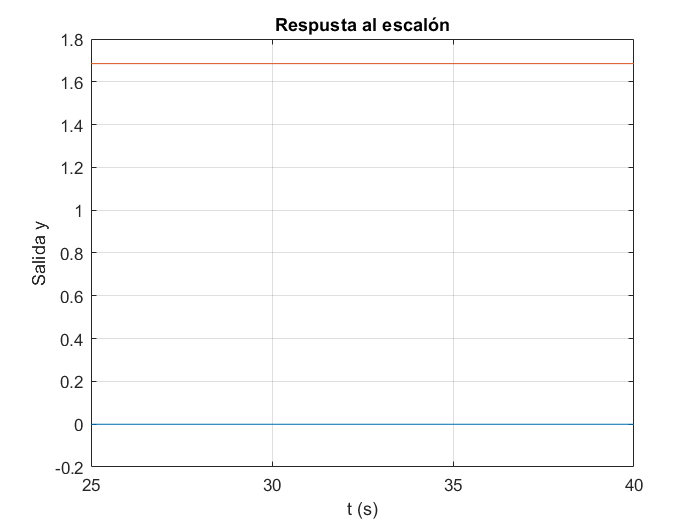

t = 25:0.01:40;
AA=A-B*K;
BB=B*K;
CC=C;
DD=D;
yc=step(AA,BB,CC,DD,1,t);

figure(3)
plot(t,yc)
grid on
title('Respusta al escalón')
xlabel('t (s)')
ylabel('Salida y')

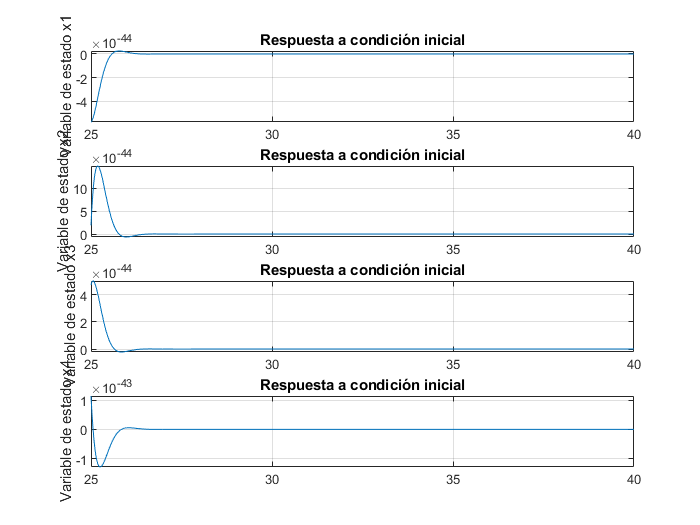



%Respuesta a la condicion inicial
sys = ss(AA, eye(4), eye(4), eye(4));
x = initial(sys,[0;0;0;1.2],t);
%[y,x,t]=step(AA,BB,C,D,1,t);
x1=[1 0 0 0]*x';
x2=[0 1 0 0]*x';
x3=[0 0 1 0]*x';
x4=[0 0 0 1]*x';

figure(4)
subplot(4,1,1);plot(t,x1),grid
title("Respuesta a condición inicial")
ylabel("Variable de estado x1")

subplot(4,1,2);plot(t,x2),grid
title("Respuesta a condición inicial")
ylabel("Variable de estado x2")

subplot(4,1,3);plot(t,x3),grid
title("Respuesta a condición inicial")
ylabel("Variable de estado x3")

subplot(4,1,4);plot(t,x4),grid
title("Respuesta a condición inicial")
ylabel("Variable de estado x4")